%Interface02PVI para o método de Euler
%
%CHAMADA DE FUNÇÕES:
% » NEuler
% » dsolve
%Alunos:
%   10/04/2021 - Francisco Ruivo .: a2021142024@isec.pt
%   10/04/2021 - Daniel Rodrigues .: a2021142013@isec.pt

clc
clear

disp('----- Métodos Numéricos para EDO/PVI ------ ');

----- Métodos Numéricos para EDO/PVI ------ 


disp(' ');

disp('----- Dados do PVI ------------------------ ');

----- Dados do PVI ------------------------ 



while 1
    strF=input('f(t,y) = ', 's');
    f=@(t,y) eval(vectorize(strF));
    try
        syms t y;
        fTeste=f(t,y);
        break;
    catch me
        disp('ERRO! Introduza uma função em t e y');
    end
end

a=str2num(input('a = ','s'));
while 1
    b=str2num(input('b = ', 's'));
    if (isscalar(b) && isreal(b) && b > a)
        break;
    else
        errordlg('Introduza um número real b, com b > a',...
                 'ERRO','modal');
    end
end

n=str2num(input('n = ','s'));
y0=str2num(input('y0 = ','s'));

yEuler=NEuler(f,a,b,n,y0);

sExata=dsolve(['Dy=', strF],...
              ['y(',num2str(a),')=',num2str(y0)]);

g=@(t) eval(vectorize(char(sExata)));
h=(b-a)/n;
t=a:h:b;
yExata=g(t);

erroEuler=abs(yExata-yEuler);
tabela=[t.', yEuler.', yExata.', erroEuler.'];
disp('----- Solução do PVI em modo tabela de valores ----')

----- Solução do PVI em modo tabela de valores ----


disp(tabela)

     5    56    56     0
     6    61    61     0
     7    66    66     0




input('Prima numa tecla para continuar')
disp('-----Solução em modo gráfico----')

-----Solução em modo gráfico----


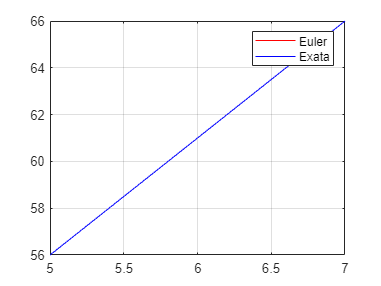

plot(t,yEuler,'-r')
hold on
plot(t,yExata, 'b')
hold off
grid on
legend('Euler','Exata')

shg;